cd 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;addpath('../Resources/Truss');startup;

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


## Ground structure

### Nodes

nodes.x = [0; 1; 2; 0; 1; 2];                       % x coordinates of nodes
nodes.y = [0; 0; 0; 1; 1; 1];                       % y coordinates of nodes
nodes.z = [0; 0; 0; 0; 0; 0];                       % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

elements.nodes1 = [1; 1; 2; 2; 2; 2; 3; 3; 4; 5];   % elements starting nodes
elements.nodes2 = [2; 5; 3; 4; 5; 6; 5; 6; 5; 6];   % elements ending nodes
nelem = numel(elements.nodes1);  % number of elements  

### Material and cross-section

elements.E = 1.0*ones(nelem, 1);    % Young moduli of individual elements

### Code numbers

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [1; 4];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [1; 4];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4;5;6];      % node indices with restricted z-direction displacements

### Load

loads.x.nodes = [];             % node indices with x-direction forces
loads.x.value = [];             % magnitude of the x-direction forces
loads.y.nodes = [2;3];          % node indices with y-direction forces
loads.y.value = [1;1];          % magnitude of the y-direction forces 
loads.z.nodes = [];             % node indices with z-direction forces
loads.z.value = [];             % magnitude of the z-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction

## Optimization parameters

V = 1;                                  % upper bound for the material volume
minimumCrossSectionArea = 1e-6;         % lower bound for cross-section areas. We need it to avoid singular stiffness matrix

## FEM

### Code numbers

codeNumbers = codeNumbsFn(elements.nodes1,elements.nodes2,nelem,dofs);

### Transformation matrix

[transformationMatrix,lengths] = transMatrixTrussFn(nelem,elements.nodes1,elements.nodes2,nodes);
% lengths
% transformationMatrix

### Design variables

crossSections = sdpvar(nelem,1);
displacements = sdpvar(nnz(dofs),1);   

### Stifness matrix

stiffnessMatrix = stiffnessMatrixTrussFn(crossSections,elements.E,lengths,transformationMatrix,nelem,codeNumbers);
% v budoucnu lepší způsob skládání matice tuhosti bez for cyklů

### Force vector

forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value ], ...
                     nnodes*3, 1);
endForces = forceVector(reshape(dofs.', 1, [])');

## Optimization problem formulation and solution

### Constraint 1: volume

volume = lengths*crossSections <= V;

### Constraint 2: equilibrium equation

equilibriumEquation = stiffnessMatrix*displacements == endForces;

### Constraint 3: lower bound for cross-section areas

nonnegativeCrossSections = crossSections>=minimumCrossSectionArea;

### Objective function

compliance = endForces'*displacements;

### Solution

ops = sdpsettings('solver','fmincon','verbose',1,'debug',1);
optimize([nonnegativeCrossSections, volume, equilibriumEquation], ...
          compliance, ops);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    1.054e+01    8.882e-15
    1       2    6.666890e+00    1.012e+00    6.319e+00    7.535e+00
    2       3    7.266257e+00    8.434e-01    6.731e+00    9.482e-01
    3       5    7.366297e+00    8.392e-01    6.804e+00    2.222e-01
    4       7    7.449387e+00    8.250e-01    6.920e+00    3.149e-01
    5       8    7.605256e+00    7.210e-01    8.082e+00    2.398e+00
    6       9    7.937500e+00    6.585e-01    9.724e+00    3.076e+00
    7      10    9.679153e+00    5.391e-01    1.902e+01    8.821e+00
    8      11    1.090339e+01    3.279e-01    1.173e+01    1.237e+01
    9      12    1.082928e+01    1.666e-01    1.813e+01    6.114e+00
   10      13    5.185822e+00    2.181e-01    2.955e+01    1.678e+01
   11    

## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(compliance));

Optimized objective: -497685.729418


fprintf('A%d = %f\n', [(1:numel(crossSections))', value(crossSections)]');

A1 = 0.000006
A2 = 0.000001
A3 = 0.000889
A4 = 0.000109
A5 = 0.000001
A6 = 0.000005
A7 = 0.037835
A8 = 0.000271
A9 = 0.000001
A10 = 0.000005


### Plotting

Plot the optimal design. Note that the dimensions are scaled.

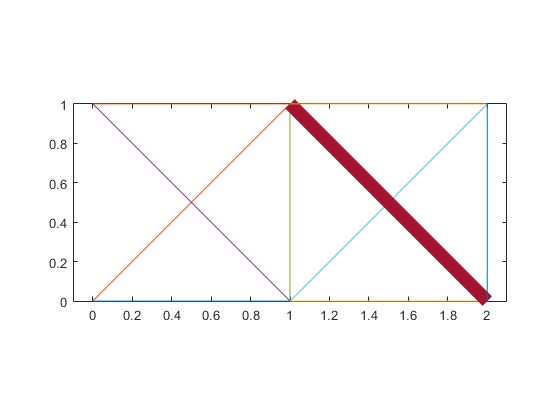

nonzeroAreas = value(crossSections)>minimumCrossSectionArea;
p = plot([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
         [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
zlim([min(nodes.z)-0.1,max(nodes.z)+0.1]);  % To avoid tight limits
axis equal